# **Astro Tide: Prediction Model **

**Load the tide constituent matrix; All the values must be imported as string.  Import format is String array - **

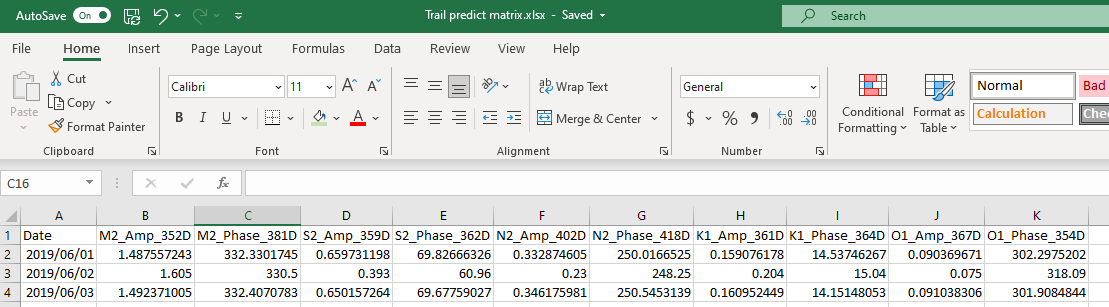

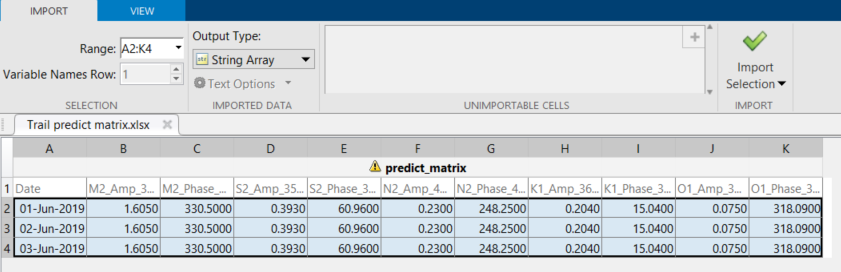

### Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 27-May-2021 17:07:52

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "Sheet1 ";
opts.DataRange = "A2:K15";

% Specify column names and types
opts.VariableNames = ["Date", "M2_Amp_352D", "M2_Phase_381D", "S2_Amp_359D", "S2_Phase_362D", "N2_Amp_402D", "N2_Phase_418D", "K1_Amp_361D", "K1_Phase_364D", "O1_Amp_367D", "O1_Phase_354D"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify variable properties
opts = setvaropts(opts, ["Date", "M2_Amp_352D", "M2_Phase_381D", "S2_Amp_359D", "S2_Phase_362D", "N2_Amp_402D", "N2_Phase_418D", "K1_Amp_361D", "K1_Phase_364D", "O1_Amp_367D", "O1_Phase_354D"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Date", "M2_Amp_352D", "M2_Phase_381D", "S2_Amp_359D", "S2_Phase_362D", "N2_Amp_402D", "N2_Phase_418D", "K1_Amp_361D", "K1_Phase_364D", "O1_Amp_367D", "O1_Phase_354D"], "EmptyFieldRule", "auto");

% Import the data
predict_matrix = readmatrix("D:\OneDrive - BUET\Advanced HAMELS 15.05.2021\Prediction Trail 1\Prediction Constituent 27_3_21 09_04_21 MATLAB Formatted.xlsx", opts, "UseExcel", false)

predict_matrix = 14×11 string array
    "27-Mar-2021"    "1.487557"    "332.3302"    "0.6597312"    "69.82666"    "0.3328746"    "250.0167"    "0.1590762"    "14.53746"    "0.09036967"    "302.2975"
    "28-Mar-2021"    "1.489129"    "332.38"      "0.6563871"    "69.88418"    "0.3376788"    "250.5854"    "0.1596542"    "14.29171"    "0.09039187"    "302.1427"
    "29-Mar-2021"    "1.490734"    "332.4012"    "0.6531454"    "69.8642"     "0.342147"     "250.8184"    "0.1602801"    "14.62915"    "0.09063523"    "302.0129"
    "30-Mar-2021"    "1.492371"    "332.4071"    "0.6501573"    "69.67759"    "0.346176"     "250.5453"    "0.1609524"    "14.15148"    "0.09103831"    "301.9085"
    "31-Mar-2021"    "1.49404"     "332.4081"    "0.6475069"    "69.28897"    "0.3496778"    "249.7802"    "0.1616702"    "13.63988"    "0.09158232"    "301.83"  
    "01-Apr-2021"    "1.495742"    "332.41"      "0.6452199"    "68.72151"    "0.3525836"    "248.7068"    "0.1624318"    "13.13203"    "0.09219243" 


m2 = 28.9841042*pi/180;
s2 = 30.0000000*pi/180;
n2 = 28.4397295*pi/180;
k1 = 15.0410686*pi/180;
o1 = 13.9430356*pi/180;
w = [m2 s2 n2 k1 o1];
predicted_data = [];

Enter the harmonic constituent file: Hard coding

for j = 1:size(predict_matrix,1)


    H = [str2num(predict_matrix(j,2)) str2num(predict_matrix(j,4)) str2num(predict_matrix(j,6)) str2num(predict_matrix(j,8)) str2num(predict_matrix(j,10))]; % replace 1 = j
    % w = [m2 s2 n2 k1 o1]
    Pdeg = [str2num(predict_matrix(j,3)) str2num(predict_matrix(j,5)) str2num(predict_matrix(j,7)) str2num(predict_matrix(j,9)) str2num(predict_matrix(j,11))]; % replace  1 = j
    R=H;
    P=Pdeg;
    % Entering prediction date & unit; Hard coding

## `Input alert: input year; soft code! from the data set predict_matrix`

    date_value = predict_matrix(j,1); % soft code from the values of predict_mat
    date_value_vec = datevec(date_value);

    year = num2str(date_value_vec(1)); % needed here! # write softcode 
    nu = 1; % unit meter
    tpred = 1; % month = 2 Hard coding % tpred = 1 for days

Converting H into R taking into 18.6 yr consideration

    ys = str2num(year); % ys needed to calculate yearly modulation of constituent by astronomical formulation
    Di = fix((ys-1901)/4) + 183;
    Nm = 259.16-19.3282*(ys-1900)-0.053*Di;
    %-------------------------------------------------
    Nmr = Nm*pi/180;
    fM2 = 1-0.037*cos(Nmr);
    fK1 = 1.006+0.115*cos(Nmr)-0.009*cos(2*Nmr);
    fO1 = 1.009+0.187*cos(Nmr)-0.015*cos(2*Nmr);
    %-------------------------------------------------
    R(1) = H(1)*fM2;
    R(2) = H(2);
    R(3) = H(3)*fM2;
    R(4) = H(4)*fK1;
    R(5) = H(5)*fO1;
    %-------------------------------------------------
    uM2 = -2.1*sin(Nmr);
    uK1 = -8.9*sin(Nmr)+0.7*sin(2*Nmr);
    uO1 = 10.8*sin(Nmr)-1.3*sin(2*Nmr)+0.2*sin(3*Nmr);
    %-------------------------------------------------
    P(1) = Pdeg(1) - uM2;
    P(2) = Pdeg(2);
    P(3) = Pdeg(3) - uM2;
    P(4) = Pdeg(4) - uK1;
    P(5) = Pdeg(5) - uO1;
    %-------------------------------------------------
    P = P*pi/180;
    MSL = 0;
    MLLW = 0;
    delh = MSL - MLLW;

Setting date vector

    bd = ['01/01/', year];
    bdv = datevec(bd);


1 month data generation` if tpred == 2`



    if tpred == 2
        ms = 12; % 7 for the month of July
        me = ms + 1;
        %-------------------------------------------------
        bdv(2) = ms;
        sd = datenum(bdv) - datenum('30-Dec-1899');
        %-------------------------------------------------
        bdv(2) = me;
        ed = datenum(bdv) - datenum('30-Dec-1899'); 
        
        % setting the time_line
        ti = 5/(60); % 5 mins gap data generated
        t = [sd*24:ti:ed*24-ti]; % Estimating the peaks only each hour
        N = length(t);
        tp = t/24;
        hp = delh*ones(1,N) + R*cos(w'*t - P'*ones(1,N))
        
        out = hp'
    end

1 day data generation` if tpred == 1 (generate prediction for 1 day)`



    if tpred == 1
        sdat = date_value; % trail june 16, 2019 % input string from the first column of the input dataset
        sdv = datevec(sdat);
        sd = datenum(sdv) - datenum('30-Dec-1899'); % start date
        ed = sd  + 1; % end date
       
        % setting the time_line
        ti = 5/(60); % 5 mins gap data generated
        t = [sd*24:ti:ed*24-ti];
        N = length(t);
        tp = t/24;
        
        
        % prediction
        hp = delh*ones(1,N) + R*cos(w'*t - P'*ones(1,N));
        
        
        predicted_data = [predicted_data hp];
    
    
    
    
    
    
    
    
    
    end
end



final_predicted_dataset = predicted_data'

final_predicted_dataset =     1.9910
    1.9978
    2.0012
    2.0013
    1.9979
    1.9911
    1.9810
    1.9675
    1.9506
    1.9303
